clear; addpath('Waveforms/HelperFuncs/');

## Wave Params

vars = load("Waveforms/BW-40-16QAM/vars.mat");
waveconfig = vars.cfgDL;
% waveform = vars.waveform;
% waveform = repmat(waveform,3,1);
waveInfo = vars.info;
carrier = nrCarrierConfig;
carrier.NCellID = waveconfig.NCellID;
carrier.SubcarrierSpacing = waveconfig.SCSCarriers{1}.SubcarrierSpacing;
carrier.NSizeGrid = waveconfig.SCSCarriers{1}.NSizeGrid;
carrier.NStartGrid = waveconfig.SCSCarriers{1}.NStartGrid

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 60
           CyclicPrefix: 'normal'
              NSizeGrid: 51
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 4
          SlotsPerFrame: 40


% waveform = h5read('qam16received_06Mar184334.hdf5','/data');
% waveform = complex(waveform.r,waveform.i);
waveform = load('gnudata/BW40_16QAM_received_10Mar134947.mat','data');
waveform = waveform.data;

% waveform = waveform(1:500000);

ofdmInfo = nrOFDMInfo(carrier,'SampleRate',50e6)

ofdmInfo = struct with fields:
                   Nfft: 1280
             SampleRate: 50000000
    CyclicPrefixLengths: [130 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 130 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90]
          SymbolLengths: [1410 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1410 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 … ] (1×56 double)
              Windowing: 45
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 4
          SlotsPerFrame: 40


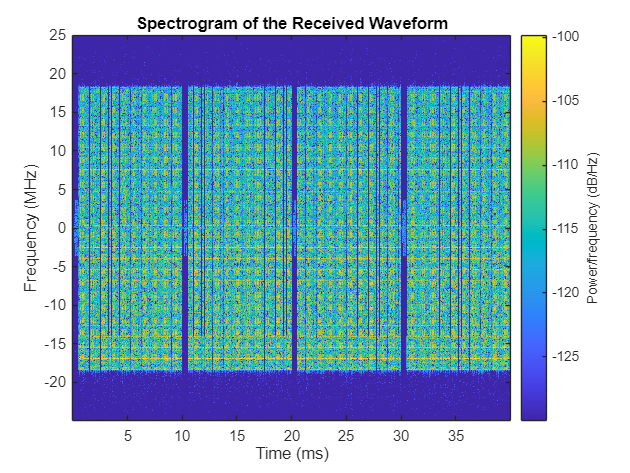

figure;
sampleRate = ofdmInfo.SampleRate;
samplesPerSubFrame = sampleRate/1000; % Fs = 1s, Subframe = 1ms 
nfft = ofdmInfo.Nfft;
spectrogram(waveform(:,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of the Received Waveform')

EVM stats for BWP idx : 1
Low edge PDSCH RMS EVM, Peak EVM, slot 2: 17.067 53.045%
Low edge DM-RS RMS EVM, Peak EVM, slot 2: 6.883 20.247%
Low edge PT-RS RMS EVM, Peak EVM, slot 2: 13.892 27.169%
High edge PDSCH RMS EVM, Peak EVM, slot 2: 17.680 54.458%
High edge DM-RS RMS EVM, Peak EVM, slot 2: 6.883 20.247%
High edge PT-RS RMS EVM, Peak EVM, slot 2: 13.883 28.556%
Low edge PDSCH RMS EVM, Peak EVM, slot 3: 16.359 49.828%
Low edge DM-RS RMS EVM, Peak EVM, slot 3: 7.513 23.707%
Low edge PT-RS RMS EVM, Peak EVM, slot 3: 12.795 22.833%
High edge PDSCH RMS EVM, Peak EVM, slot 3: 17.286 51.328%
High edge DM-RS RMS EVM, Peak EVM, slot 3: 7.513 23.707%
High edge PT-RS RMS EVM, Peak EVM, slot 3: 12.808 27.545%
Low edge PDSCH RMS EVM, Peak EVM, slot 4: 17.131 46.902%
Low edge DM-RS RMS EVM, Peak EVM, slot 4: 7.746 20.567%
Low edge PT-RS RMS EVM, Peak EVM, slot 4: 13.819 25.792%
High edge PDSCH RMS EVM, Peak EVM, slot 4: 17.733 48.937%
High edge DM-RS RMS EVM, Peak EVM, slot 4: 7.746 20.567%
Hig

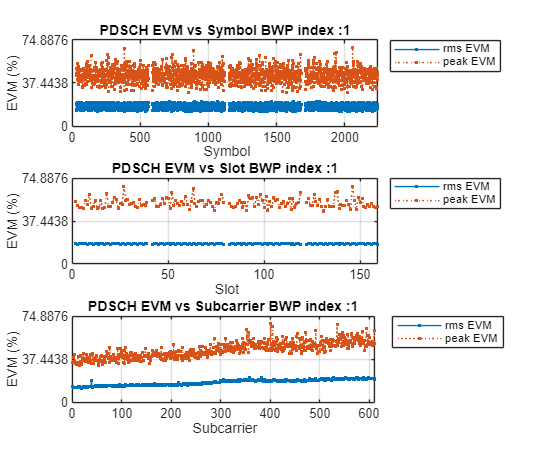

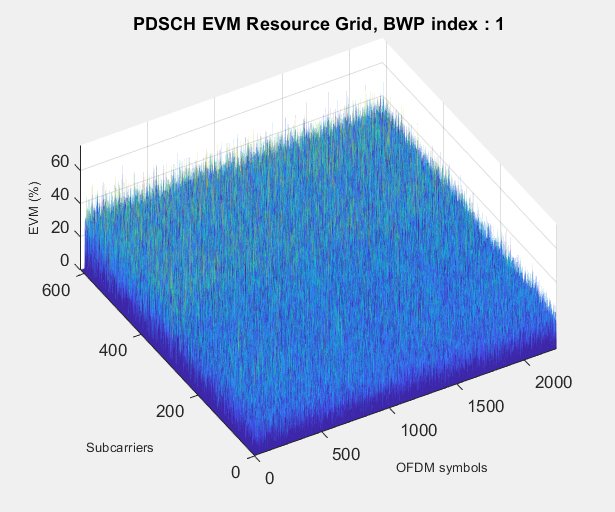

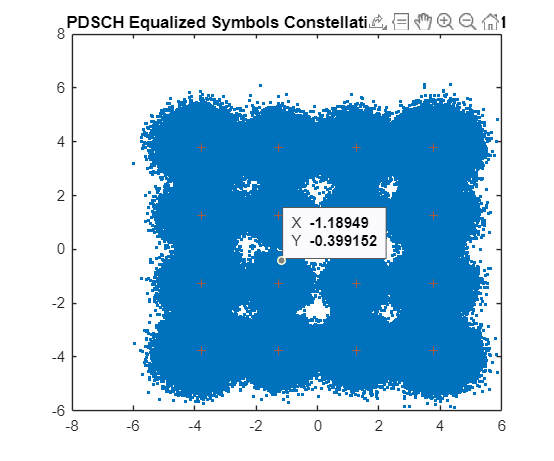

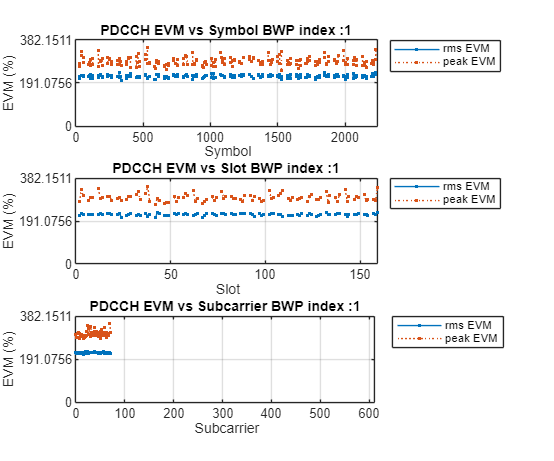

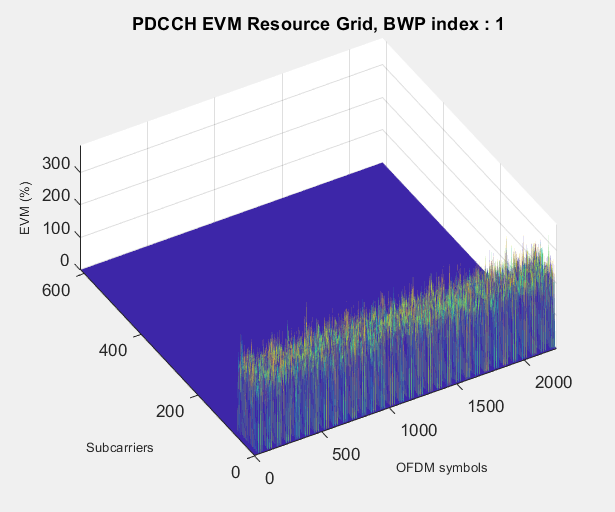

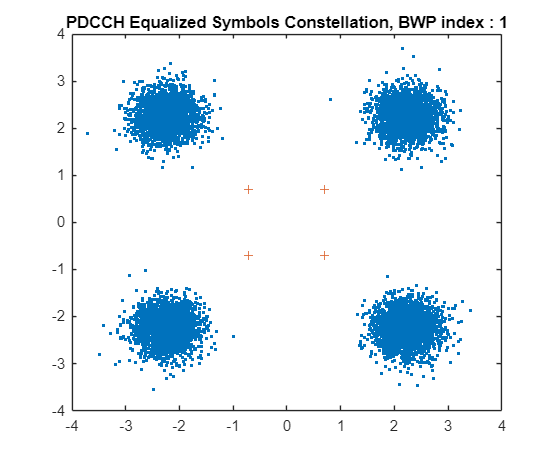

Averaged overall PDSCH RMS EVM: 17.515%
Overall PDSCH Peak EVM = 68.0797%
Averaged overall PDCCH RMS EVM: 220.162%
Overall PDCCH Peak EVM = 347.4101%


cfg = struct();
cfg.Evm3GPP = true;
cfg.TargetRNTIs = 0;
cfg.PlotEVM = true;
cfg.DisplayEVM = true;
cfg.IQImbalance = true;
cfg.SampleRate = 50e6;
cfg.CorrectCoarseFO = true;
cfg.CorrectFineFO = true;
cfg.TimeSyncEnable = false;
% cfg.UseWholeGrid = true;
cfg.ExcludeDC = true;
cfg.DCOffset = true;
waveconfig.NumSubframes = ceil(size(waveform,1)/samplesPerSubFrame);
[evmInfo,eqSym,refSym] = hNRDownlinkEVM(waveconfig,waveform,cfg);